# **Controls for parameter tuning**

Linear classification

Holdout 50 or 80% --> community uses 80%

 --> maybe check a few cells

============

OBSERVATIONS

============

Analysis on MODULATION

==> WHAT ABOUT PEAK MAGNITUDE

==> WHAT NOT JUST THE PEAKS (full signal)

-  Encoder

-  EyeCam_Wheel --> check against encoder

-  L Forelimb

-  R Forelimb

-  Trunk (highest for 3-4 cells, so keep for now)

-  BodyCam LWhisker : The good one (behind, on black background)

- BodyCam RWhisker (on the whiskerpad, from the front + cuetip)

- Perioral

- trigger

- F0

**  shuffles (temporal and spatial permutation, separately, for all Conditions)

Excluded : 

- Laser

- BodyCam Eye --> meh

- Eycam whiskerpad (just check 09-12 exp 9-11 exp2 04-30-exp4

- eyecam Eye (check 09-04 exp2)

- NOT RT3D_MC BUT BASELINE F0 instead

============

PREDICTORS

============

* All ROIs

* Highest PHATE (+ and - for PHATEs 1-3)

* Perisomatic ROIS (6)

* 6 random ROIs 

* High PHATES GROUPS (6 ROIs of the PHATES 1->3 + and -)

# 1. Load experiment

You can use this script as a standalone function. In this case, indicate the path to an extracted arboreal_scan folder, or to an arboreal_scan_experiment mat file here

path_to_use = 'C:\Users\Antoine.Valera\MATLAB\newextraction_raw_zscored\2019-10-03_exp_5';

You can use this script in a loop. To do this, 

- create a variable called use_existing and set it to true.

- create a loop with the exported experiment path called expe_folder. 

The expe_folder path can point to

- an extracted expe_folder, in this case the arboreal_scan_experiment object will be generated and saved. If expe_folder contains an exisiting arboreal_scan_experiment, the code will ask you want to do, which will pause the excution of the loop.

- an arboreal_scan_experiment object (faster)

if exist('use_existing','var') && use_existing == true && exist('expe_folder','var') && ischar(expe_folder)
    path_to_use = expe_folder
elseif exist('use_existing','var')
    error('to use this script in a loop, read the procedure explained in the code')    
end

obj = arboreal_scan_experiment(path_to_use);


if contains(path_to_use,'.mat')
    folder_to_use = parse_paths(fileparts(path_to_use));
else
    folder_to_use = path_to_use;
end


# 2. Define the Analysis Settings

## Arboreal Scan settings

obj.detrend                         = 0; % -1; %'auto'
obj.filter_win                      = -1; % 
obj.rendering                       = 1;
obj.process({'distance',50});       % will use obj.filter_win and obj.rendering
obj.get_dimensionality([],'phate','peaks_subtracted',[]);
obj.cluster_factors('dbscan',-5)

## Machine Learning settings

use_classifier  = false;                % true or false
method          = 'linear';             % 'linear' or 'svm'    
variable_type   = 'peaks_subtracted';   % 'peak_subtracted' or any other set of conditions / timepoints
behaviours      = {'encoder','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger','baseline'};
%behaviours      = {'encoder','BodyCam_L_whisker'}; 
N_iter          = 10;                   % N iterations
KFold           = 5; 
holdout         = 0;                    % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
rendering       = 1;                    % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.

% For lag analysis, define the range and step size
time_step       = 0.5;
time_ext        = 30;
sr              = 1/nanmedian(obj.timescale.sr);
lag_list        = [(0:time_step:time_ext)*-1, (0:time_step:time_ext)];
lag_list        = unique(round(sort(lag_list) * sr))

return

close all

# 3. Regular Behaviour Prediction

## On all ROIs

ROI_selection       = [];
[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs',... % Bar chart title
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there

save([folder_to_use, 'ML_All_ROIs'],'result','R','-v7.3')

## On ROIs with High Phate magnitude (0-lag)

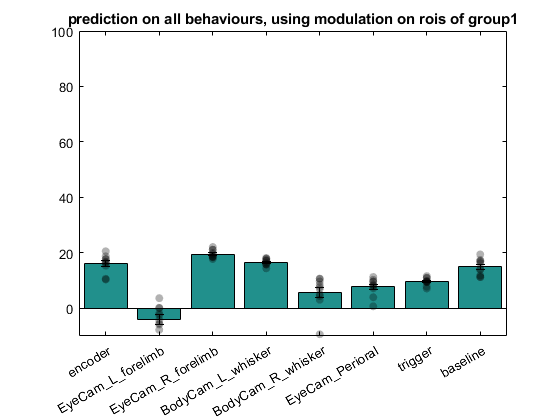

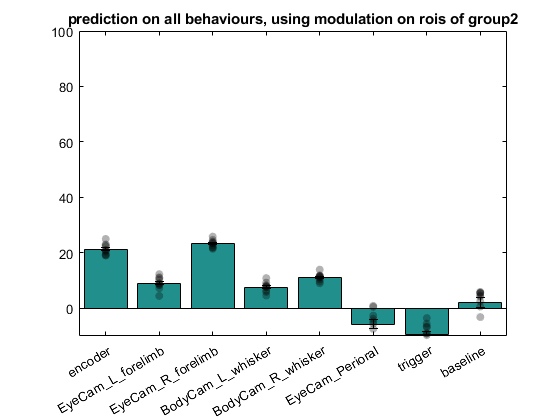

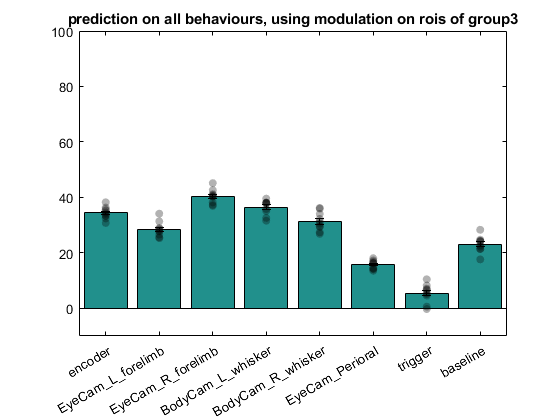

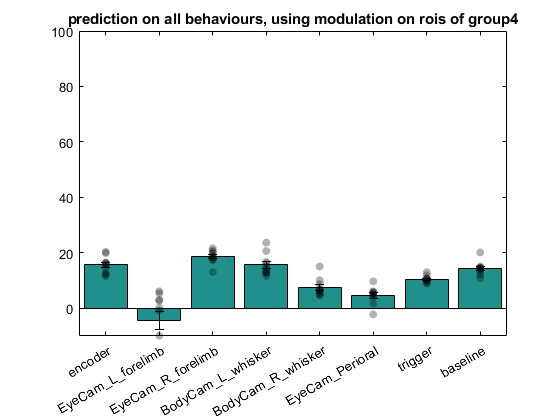

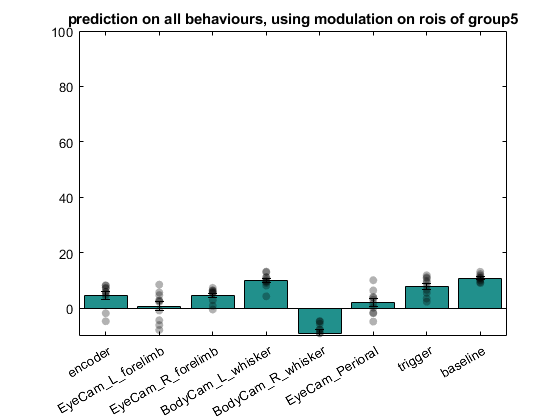

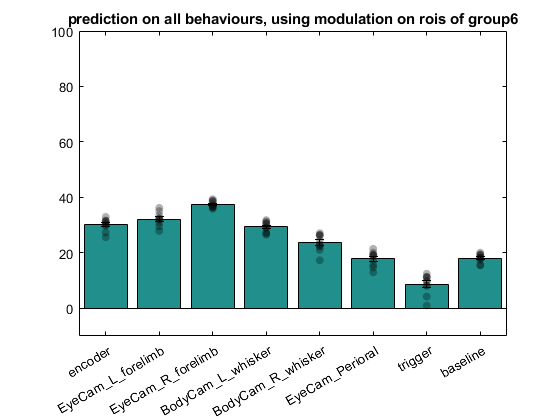

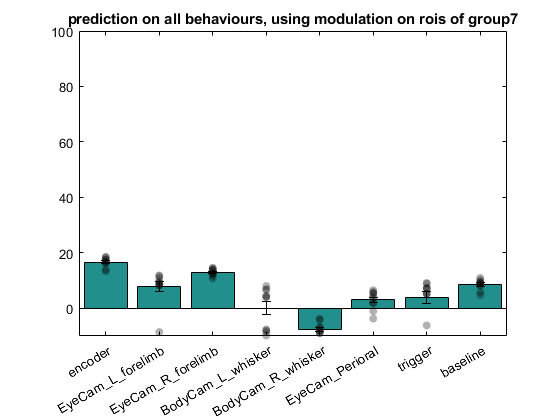

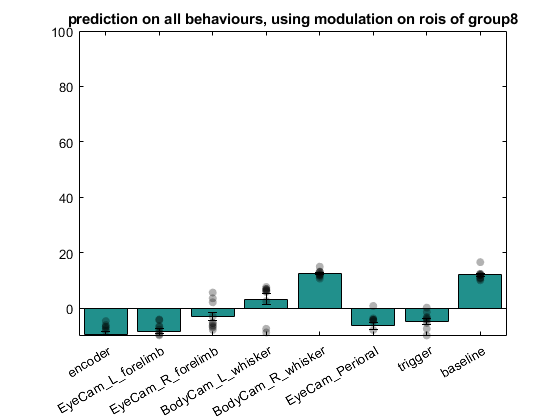

N_phates        = 3;    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes

try
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
end

% To study phates 1-3 up/down together and avg'd across ROIs (e.g. contents of cell array are avg'd prior to running ML) 
% e.g. if the cell 'cares' about avg. signals coming out of larger than our ROIs compartments
ROI_selection       = groups;
[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score

                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on High Phates',... % Bar chart title
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there


cb =   ColorBar (Normalized predictive score , (normed to max predictibility per behaviour)) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 7.6500
    Position: [0.3832 0.1095 0.0239 0.8143]
       Units: 'normalized'

  Show all properties


save([folder_to_use, 'ML_High_Phates'],'result','R','-v7.3')

## On individual ROI groups identified by individual Phates (0-lag)

% to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% need to know what is in groups for this to be interpretable
N_phates        = min(obj.dimensionality.n_factors, 9);    % N dimensions
cutoff          = 2;    % 0 is just min and max

cb =   ColorBar (Normalized predictive score , (normed to max predictibility in phate)) with properties:

    Location: 'eastoutside'
      Limits: [0 1]
    FontSize: 7.6500
    Position: [0.8242 0.1095 0.0241 0.8143]
       Units: 'normalized'

  Show all properties


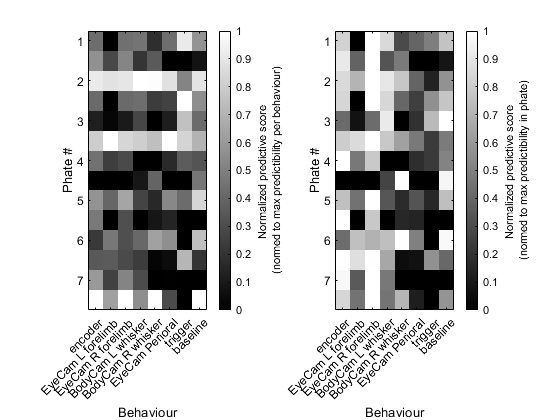

bidirectional   = true; % Postive AND negative magnitudes
groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
extracted_beh   = prepare_behaviour_data(obj, behaviours);

All_R           = {};
result          = {};
step            = 2;
for gp_idx = 1:step:numel(groups)
    temp_group = unique([groups{gp_idx : gp_idx+step - 1}]);
    [result{gp_idx},~,~, All_R{gp_idx}]   = predict_behaviours(obj,  use_classifier ,... % true or false
                                                                     method         ,... % 'linear' or 'svm'
                                                                     variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                     extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                                     temp_group     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                     N_iter         ,... % N iterations
                                                                     false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                                     'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                                     'rendering', true     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                                     'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                                     'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                                     'kfold', KFold             ,...
                                                                     'title', ['Prediction on all behaviours, using modulation on ROIs of group ', num2str(gp_idx : gp_idx+step - 1)],... % Bar chart title
                                                                     'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there
end

f1 = figure();subplot(1,2,1);
a = cell2mat(All_R)';%a(a < 20) = 0;
imagesc(a ./ max(a));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'}
xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:N_phates*2);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');

subplot(1,2,2);a = cell2mat(All_R)';%a(a < 20) = 0;
imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'}
xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:N_phates*2);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
save_myfig(f1,[folder_to_use, 'ROI groups identified by individual Phates (0-lag)'],{'png','pdf'})

save([folder_to_use, 'ML_individual_Phates'],'result','All_R','groups','-v7.3')

## On ROIs identified by clustering

obj.cluster_factors('dbscan',-5);
ROI_selection       = obj.dimensionality.clust_groups; 

[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on clusters of ROIs',... % Bar chart title
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there

save([folder_to_use, 'ML_clusters'],'result','R','-v7.3')

## On individual ROI groups following clustering

groups          = obj.dimensionality.clust_groups; 
extracted_beh   = prepare_behaviour_data(obj, behaviours);
All_R           = {};
result          = {};
for gp_idx = 1:numel(groups)
    [result{gp_idx},~,~, All_R{gp_idx}]= predict_behaviours(obj,use_classifier ,... % true or false
                                                         method         ,... % 'linear' or 'svm'
                                                         variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                         extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                         groups{gp_idx}     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                         N_iter         ,... % N iterations
                                                         false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                         'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                         'rendering', true     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                         'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                         'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                         'kfold', KFold             ,...
                                                         'title', ['Prediction on all behaviours, using modulation on ROIs of group', num2str(gp_idx)],... % Bar chart title
                                                         'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there
end

f2 = figure();subplot(1,2,1);
a = cell2mat(All_R)';%a(a < 20) = 0;
imagesc(a ./ max(a));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'}
xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');

subplot(1,2,2);a = cell2mat(All_R)';%a(a < 20) = 0;
imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(gray);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'}
xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
save_myfig(f2,[folder_to_use, 'individual ROI groups following clustering'],{'png','pdf'});

save([folder_to_use, 'ML_individual_clusters'],'result','All_R','groups','-v7.3')

## On perisomatic ROIs

ROI_selection       = num2cell(obj.ref.indices.somatic_ROIs); % Get perisomatic ROIs (i.e 1st ROI of each branch emerging from the soma OR lowest ROIS of apical dendrite when no soma.
[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on perisomatic ROIs',... % Bar chart title
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there

save([folder_to_use, 'ML_perisomatic_ROIs'],'result','R','-v7.3')
%load_full_experiment('D:/SuperBackup Laptop TO DELETE/LaCie/Curated Data/2019-10-01/experiment_1', '', 2, -5, true, '', '', 'smoothing', [-1,1], 'rendering_mode', 'realistic','rendering',true,'ROIs',obj.ref.indices.somatic_ROIs);

# 4. Controls

## 4.1. Time Shuffling

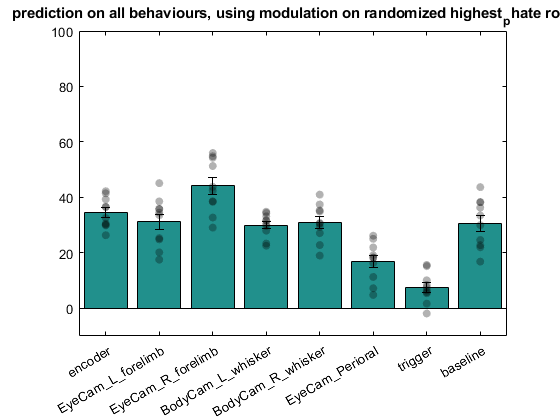

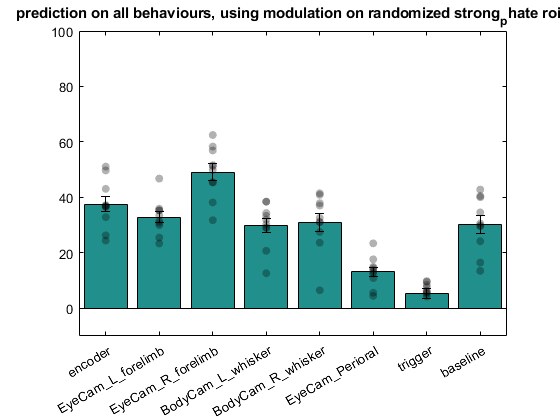

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

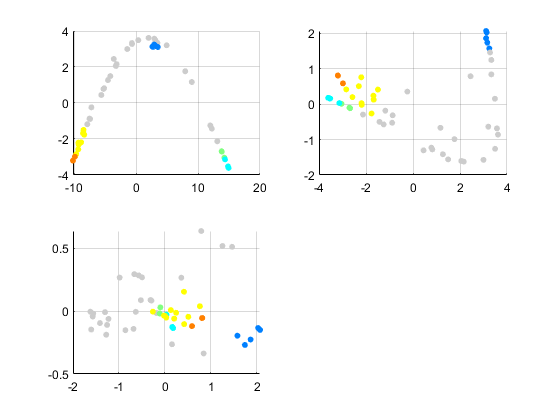

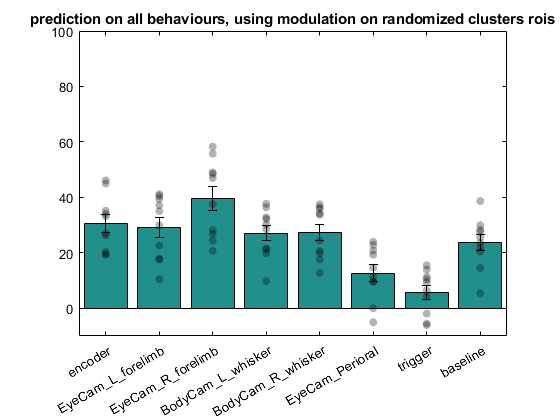

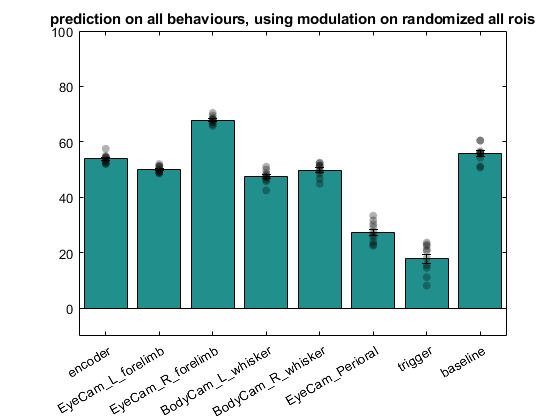

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled',... % Bar chart title
                                             'shuffling','events',... % Shuffling of Ca2+ events
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there

## 4.2. Spatial Shuffling

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled',... % Bar chart title
                                             'shuffling','ROIs',... % Shuffling of modulation across ROis during a same event
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there


## 4.3. Trial Shuffling

% Using the entire dendritic tree on the baseline and encoder

lag_idx = 1

lag_idx = 2

lag_idx = 3

lag_idx = 4

lag_idx = 5

lag_idx = 6

lag_idx = 7

lag_idx = 8

lag_idx = 9

lag_idx = 10

lag_idx = 11

lag_idx = 12

lag_idx = 13

lag_idx = 14

lag_idx = 15

lag_idx = 16

lag_idx = 17

lag_idx = 18

lag_idx = 19

lag_idx = 20

lag_idx = 21

lag_idx = 22

lag_idx = 23

lag_idx = 24

lag_idx = 25

lag_idx = 26

lag_idx = 27

lag_idx = 28

lag_idx = 29

lag_idx = 30

lag_idx = 31

lag_idx = 32

lag_idx = 33

lag_idx = 34

lag_idx = 35

lag_idx = 36

lag_idx = 37

lag_idx = 38

lag_idx = 39

lag_idx = 40

lag_idx = 41

lag_idx = 42

lag_idx = 43

lag_idx = 44

lag_idx = 45

lag_idx = 46

lag_idx = 47

lag_idx = 48

lag_idx = 49

lag_idx = 50

lag_idx = 51

lag_idx = 52

lag_idx = 53

lag_idx = 54

lag_idx = 55

lag_idx = 56

lag_idx = 57

lag_idx = 58

lag_idx = 59

lag_idx = 60

lag_idx = 61

lag_idx = 62

lag_idx = 63

lag_idx = 64

lag_idx = 65

lag_idx = 66

lag_idx = 67

lag_idx = 68

lag_idx = 69

lag_idx = 70

lag_idx = 71

lag_idx = 72

lag_idx = 73

lag_idx = 74

lag_idx = 75

lag_idx = 76

lag_idx = 77

lag_idx = 78

lag_idx = 79

lag_idx = 80

lag_idx = 81

lag_idx = 82

lag_idx = 83

lag_idx = 84

lag_idx = 85

lag_idx = 86

lag_idx = 87

lag_idx = 88

lag_idx = 89

lag_idx = 90

lag_idx = 91

lag_idx = 92

lag_idx = 93

lag_idx = 94

lag_idx = 95

lag_idx = 96

lag_idx = 97

lag_idx = 98

lag_idx = 99

lag_idx = 100

lag_idx = 101

lag_idx = 102

lag_idx = 103

lag_idx = 104

lag_idx = 105

lag_idx = 106

lag_idx = 107

lag_idx = 108

lag_idx = 109

lag_idx = 110

lag_idx = 111

lag_idx = 112

lag_idx = 113

lag_idx = 114

lag_idx = 115

lag_idx = 116

lag_idx = 117

lag_idx = 118

lag_idx = 119

lag_idx = 120

lag_idx = 121

trial_shuff_results = {}; 

ans = datetime
   10-Mar-2023 13:46:09


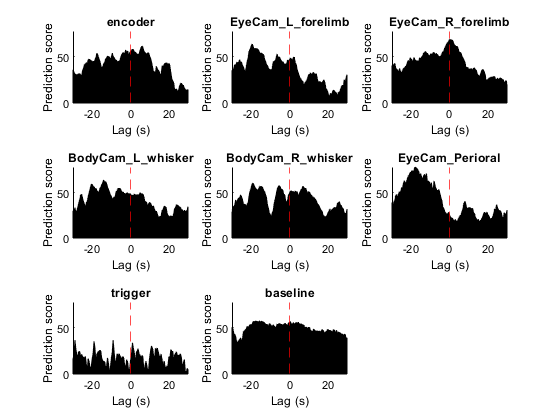

shuffled_beh  = strcat(behaviours, '_shuffle');
shuffled_beh = reshape([behaviours; shuffled_beh],[],1)';
%shuffled_beh  = {'encoder','encoder_shuffle','EyeCam_L_forelimb','EyeCam_L_forelimb_shuffle','EyeCam_R_forelimb','EyeCam_R_forelimb_shuffle','BodyCam_L_whisker','BodyCam_L_whisker_shuffle','BodyCam_R_whisker','BodyCam_R_whisker_shuffle','EyeCam_Perioral','EyeCam_Perioral_shuffle','trigger','trigger_shuffle','baseline','baseline_shuffle'};
%shuffled_beh  = {'baseline','baseline_shuffle','encoder'}

%variable_type = 1:100:15000 % mimics the slow baseline drift measurement

% need to convert the time points t into amplitudes for valid ROIs, then
% feed this to variable_type
% below is just a first approx/ball park estimate:
% 

% tt = find(obj.get_tp_for_condition('peaks'))
% num_ev = numel(vertcat(obj.event.peak_time{:})); %could use this or several other of the obj.event outputs to get # of events
% rand_timepoints = sort(tt(randi(numel(tt),1,num_ev)))

[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             shuffled_beh   ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction selected behaviours with and without shuffling, using modulation on all ROIs',... % Bar chart title
                                             'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there


% figure();plot(obj.rescaled_traces(:,77));hold on;scatter(variable_type, obj.rescaled_traces(variable_type,77),'r','filled')


## 4.4 ROI Groups Shuffling

## On randomized groups of ROIs

All_R   = {};
idx     = 0;
result  = {};
for condition = {'highest_phate', 'strong_phate', 'clusters', 'all'}
    idx = idx + 1;
    switch condition{1}
        case 'highest_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 0;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);      
        case 'strong_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 5;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional); 
        case 'clusters'
            obj.cluster_factors('dbscan',-5);
            ROI_selection   = obj.dimensionality.clust_groups;        
        case 'all'
            ROI_selection   = [];        
    end

    [result{idx},~,~,All_R{idx}] = predict_behaviours(obj,use_classifier ,... % true or false
                                                 method         ,... % 'linear' or 'svm'
                                                 variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints

lag_idx = 1

lag_idx = 2

lag_idx = 3

lag_idx = 4

lag_idx = 5

lag_idx = 6

lag_idx = 7

lag_idx = 8

lag_idx = 9

lag_idx = 10

lag_idx = 11

lag_idx = 12

lag_idx = 13

lag_idx = 14

lag_idx = 15

lag_idx = 16

lag_idx = 17

lag_idx = 18

lag_idx = 19

lag_idx = 20

lag_idx = 21

lag_idx = 22

lag_idx = 23

lag_idx = 24

lag_idx = 25

lag_idx = 26

lag_idx = 27

lag_idx = 28

lag_idx = 29

lag_idx = 30

lag_idx = 31

lag_idx = 32

lag_idx = 33

lag_idx = 34

lag_idx = 35

lag_idx = 36

lag_idx = 37

lag_idx = 38

lag_idx = 39

lag_idx = 40

lag_idx = 41

lag_idx = 42

lag_idx = 43

lag_idx = 44

lag_idx = 45

lag_idx = 46

lag_idx = 47

lag_idx = 48

lag_idx = 49

lag_idx = 50

lag_idx = 51

lag_idx = 52

lag_idx = 53

lag_idx = 54

lag_idx = 55

lag_idx = 56

lag_idx = 57

lag_idx = 58

lag_idx = 59

lag_idx = 60

lag_idx = 61

lag_idx = 62

lag_idx = 63

lag_idx = 64

lag_idx = 65

lag_idx = 66

lag_idx = 67

lag_idx = 68

lag_idx = 69

lag_idx = 70

lag_idx = 71

lag_idx = 72

lag_idx = 73

lag_idx = 74

lag_idx = 75

lag_idx = 76

lag_idx = 77

lag_idx = 78

lag_idx = 79

lag_idx = 80

lag_idx = 81

lag_idx = 82

lag_idx = 83

lag_idx = 84

lag_idx = 85

lag_idx = 86

lag_idx = 87

lag_idx = 88

lag_idx = 89

lag_idx = 90

lag_idx = 91

lag_idx = 92

lag_idx = 93

lag_idx = 94

lag_idx = 95

lag_idx = 96

lag_idx = 97

lag_idx = 98

lag_idx = 99

lag_idx = 100

lag_idx = 101

lag_idx = 102

lag_idx = 103

lag_idx = 104

lag_idx = 105

lag_idx = 106

lag_idx = 107

lag_idx = 108

lag_idx = 109

lag_idx = 110

lag_idx = 111

lag_idx = 112

lag_idx = 113

lag_idx = 114

lag_idx = 115

lag_idx = 116

lag_idx = 117

lag_idx = 118

lag_idx = 119

lag_idx = 120

lag_idx = 121

                                                 behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints

ans = datetime
   10-Mar-2023 14:03:32


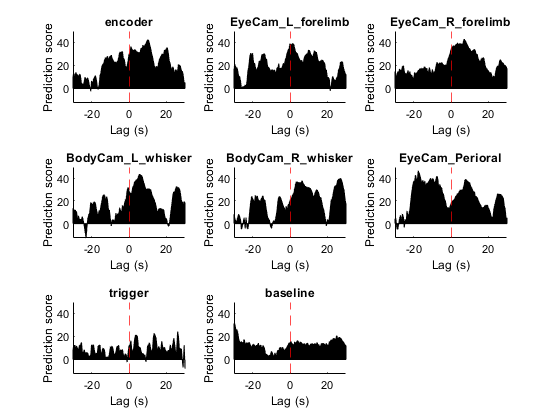

                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                 N_iter         ,... % N iterations
                                                 -1             ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                 'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                 'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                 'kfold', KFold             ,...
                                                 'title', ['Prediction on all behaviours, using modulation on randomized ',condition{1},' ROIs'],... % Bar chart title
                                                 'savefig',path_to_use);  % Save figure. If you set a path, the figure is saved there
end

## 4.5 Block Shuffling

starts =            1          69         137         205         609        1013        1417        1821        2225        2629        3033        3437        3841        4245        4649        5053        5461        5869        6277        6685        7093        7501        7909        8317        8725        9129        9533        9937       10341       10745       11149       11553       11957       12361       12765


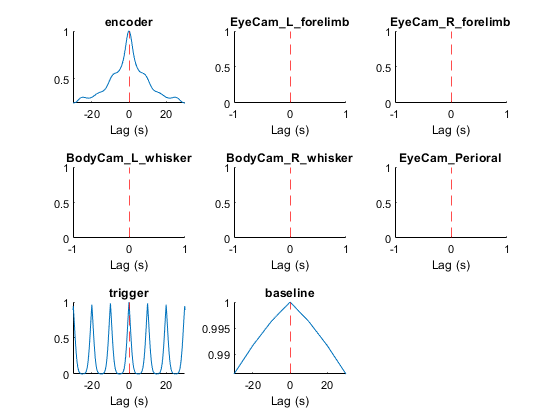

starts =            1          69         137         205         609        1013        1417        1821        2225        2629        3033        3437        3841        4245        4649        5053        5461        5869        6277        6685        7093        7501        7909        8317        8725        9129        9533        9937       10341       10745       11149       11553       11957       12361       12765


Error using internal.stats.cvpartitionImpl>checkindex (line 441)
Index must be a positive integer less than or equal to the number of test sets.

Error in internal.stats.cvpartitionImpl/test (line 229)
                    checkindex(i,cv.NumTestSets);

Error in <a hre

ROI_selection       = [];
shuffle_win_size    = 1;
[result,~,~,R]      = predict_behaviours(obj,use_classifier ,... % true or false
                                            method         ,... % 'linear' or 'svm'
                                            variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                            behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                            ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                            10             ,... % N iterations
                                            false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                            'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                            'rendering', true     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                            'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score..
                                            'holdout', 0.2         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                            'Kfold', 1             ,...
                                            'block_shuffling'      ,shuffle_win_size/(nanmedian(diff(obj.t))), ...
                                            'title', 'Prediction on all behaviours, using block shuffling');  % Save figure. If you set a path, the figure is saved there

# 5. Introducing Time Lag

## 5.1. Time lag for all ROIs



% Extract behaours first to prevent doing it every time inside the for-loop
extracted_beh   = prepare_behaviour_data(obj, behaviours);
ROI_selection   = [];
R               = {};

%% Run simulation for every lag value
for lag_idx = 1:numel(lag_list) 
    lag_idx
    lag = lag_list(lag_idx);
    [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             ['peaks_subtracted','_lag',num2str(lag)]       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             5              ,... % N iterations
                                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', KFold             ,...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag/10),' s'],... % Bar chart title
                                                             'savefig',false);  % Save figure. If you set a path, the figure is saved there
end

%% Plot lag results
a = cell2mat(R);x = lag_list/sr;
f3 = figure();tiledlayout('flow');
for beh = 1:numel(behaviours)
    axes(beh) = nexttile    ;  
    patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k');
    title(strrep(behaviours{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
    xline(0,'r--');
end
linkaxes(axes, 'xy')
save_myfig(f3,[folder_to_use, 'All ROI groups with time lag'],{'png','pdf'})

f5 = figure(2);clf();
tiledlayout('flow');
for beh = 1:size(extracted_beh.raw_behaviours, 1)
    axes(beh) = nexttile    ;
    title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
    plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
    xlabel('Lag (s)');xline(0,'r--')
end
save_myfig(f5,[folder_to_use, 'behaviours crosscorrelation during full recording'],{'png','pdf'})

save([folder_to_use, 'lag_All_ROIs'],'All_R','lag_list','sr','groups','-v7.3')

## 5.2. Time lag for High Phates

N_phates        = 3;    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes

try
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
end

close all

% Extract behaours first to prevent doing it every time inside the for-loop
extracted_beh   = prepare_behaviour_data(obj, behaviours);
ROI_selection   = groups;
R               = {};

%% Run simulation for every lag value
for lag_idx = 1:numel(lag_list) 
    lag_idx
    lag = lag_list(lag_idx);
    [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             ['peaks_subtracted','_lag',num2str(lag)]       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             5              ,... % N iterations
                                                             false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', KFold             ,...
                                                             'title', ['Prediction on all behaviours, using modulation on high Phates with a lag of ',num2str(lag/10),' s'],... % Bar chart title
                                                             'savefig',false);  % Save figure. If you set a path, the figure is saved there
end

%% Plot lag results
a = cell2mat(R);x = lag_list/sr;
f4 = figure();tiledlayout('flow');
for beh = 1:numel(behaviours)
    axes(beh) = nexttile    ;  
    patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k');
    title(strrep(behaviours{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
    xline(0,'r--');
end
linkaxes(axes, 'xy')
save_myfig(f4,[folder_to_use, 'High Phates with time lag'],{'png','pdf'})

save([folder_to_use, 'lag_High_phates'],'All_R','lag_list','sr','groups','-v7.3')

# 6. Focusing on specific epochs

extracted_beh   = prepare_behaviour_data(obj, behaviours);

events_tp       = find(obj.get_tp_for_condition('peaks'));
ROI_selection   = [];
R               = {};
All_R           = {};
% Note : You cannot test trigger by filtering out all triggers
close all
phase_list = {'free', 'whisker', 'puff'};
for idx = 1:numel(phase_list)
    phase           = phase_list{idx};
    in_phase        = cellfun(@(x) any(contains(x, phase,'IgnoreCase',true)), obj.logs); % puff, free, whisker
    valid_tp        = false(size(obj.t));
    starts          = cumsum([1, obj.timescale.tp])
    for trial = 1:numel(in_phase)
        if in_phase(trial)
            valid_tp(starts(trial):(starts(trial+1)-1)) = true;
        end    
    end
    
    for lag = 1:numel(lag_list)    
        [result_linear,~,~, R{lag}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                                 method         ,... % 'linear' or 'svm'
                                                                 {['peaks_subtracted','_lag',num2str(lag_list(lag))], valid_tp}       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                 extracted_beh, ...%,'encoder','BodyCam_L_whisker'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                 5              ,... % N iterations
                                                                 false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
                                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                                 'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                                 'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                                 'kfold', KFold             ,...
                                                                 'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag_list(lag)/10),' s during the ',phase,' Phase'],... % Bar chart title
                                                                 'savefig',false);  % Save figure. If you set a path, the figure is saved there
    end
    All_R{idx} = R;
    
        
    %% Plot lag results
    a = cell2mat(All_R{idx});x = lag_list/sr;
    f4 = figure();tiledlayout('flow');
    for beh = 1:numel(behaviours)
        axes(beh) = nexttile    ;  
        patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k');
        title(strrep(behaviours{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
        xline(0,'r--');
    end
    linkaxes(axes, 'xy')
    save_myfig(f4,[f, 'Prediction on all behaviours, using modulation on all ROIs during the ',phase,' Phase'],{'png','pdf'})

    close all
    f5 = figure(2);clf();
    tiledlayout('flow');
    for beh = 1:size(extracted_beh.raw_behaviours, 1)
        axes(beh) = nexttile    ;
        title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
        plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
        xlabel('Lag (s)');xline(0,'r--')
    end
    save_myfig(f5,[folder_to_use, 'behaviours crosscorrelation during the ',phase,' Phase'],{'png','pdf'})
end

save([folder_to_use, 'lag_High_phates'],'All_R','lag_list','sr','groups','-v7.3')

# 7. Beta Coefficents

## 7.1 Beta coef for single behaviour

% % Run Prediction for a specific behaviour
% % Note that you need to get the beta coefs for the entire tree, or it can
% % be complicated to display
% ROI_selection       = [];
% result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
%                                              method         ,... % 'linear' or 'svm'
%                                              variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                              {'encoder'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                              ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                              N_iter         ,... % N iterations
%                                              false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
%                                              'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
%                                              'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
%                                              'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
%                                              'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
%                                              'kfold', KFold             ,...
%                                              'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title
% 
% all_scores = extract_ML_coefs(obj, result_linear, true, 'beta')

## 7.2 Display Beta coefs

% % Run with deifferent lags, and display beta coef in an animation
% extracted_beh   = prepare_behaviour_data(obj, 'trigger');
% 
% lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
% lag_list        = unique(round(lag_list * sr));
% R               = {};
% 
% for lag_idx = 1:numel(lag_list) 
%     lag_idx
%     lag = lag_list(lag_idx);
%     [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
%                                                  method         ,... % 'linear' or 'svm'
%                                                  ['peaks_subtracted','_lag',num2str(lag)],...
%                                                  extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                                  ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                                  1              ,... % N iterations
%                                                  false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
%                                                  'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
%                                                  'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
%                                                  'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
%                                                  'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
%                                                  'kfold', KFold             ,...
%                                                  'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title
% 
%     all_scores{lag_idx} = extract_ML_coefs(obj, result_linear, false, 'beta');
% end
% 
% %% Note : small video of the beta coefs + predictive score for a giver behaviour, to capture with OBS 
% values = cell2mat(cellfun(@(x) nanmean(x{1})', all_scores, 'UniformOutput', false))';
% for lag_idx = 1:numel(lag_list) 
%     figure(123); clf();
%     ax1 = subplot(1,2,1);beh_idx = 1;
%     obj.ref.plot_value_tree(values(lag_idx,:), cell2mat(result_linear{1}.used_ROIs),'',['encoder with lag = ',num2str(lag_list(lag_idx))],'',ax1);
% %     pause(0.3)
%     ax2 = subplot(1,2,2);cla();beh_idx = 1;
%     a = cell2mat(R);x = lag_list/sr;
%     patch([x,fliplr(x)], [a(beh_idx, :), zeros(size(a(beh_idx, :)))], 'k')
%     title(strrep(extracted_beh.original_behaviour_list{beh_idx},'_',' '));xlabel('Lag (s)');ylabel('Prediction score');
%     xline(x(lag_idx),'b-');
%     xline(0,'r--');pause(0.1)
% end
% %obj.animate_experiment(values, '', cell2mat(result_linear{1}.used_ROIs))

% 
% for sm = [0,1,10]
%     extracted_beh   = prepare_behaviour_data(obj, behaviours,true, sm);
%     figure();clf();
%     tiledlayout('flow');
%     for beh = 1:size(extracted_beh.raw_behaviours, 1)
%         axes(beh) = nexttile    ;
%         title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
%         plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
%         xlabel('Lag (s)');xline(0,'r--')
%     end
% end

% for beh = behaviours
% %beh = 'L_forelimb';
%     raw_beh = get_behaviours(obj, beh{1}, false, true, true, false);
%     raw_beh = raw_beh{1};
%     test = cellfun(@(x) x.value, raw_beh, 'uni', false);
%     test = vertcat(test{:});
%     test(isnan(test)) = 0;
%     figure();plot(xcorr(vertcat(test), 150));title(beh{1})
% end

## Setp 1 identify a group of Phate discovered ROIs that have a strong specific tuning

% 
% 
% 
% Phate_nb = 5;
% figure();title(['Phate # ',num2str(Phate_nb)])
% plot(obj.t,nanmean(obj.rescaled_traces(:,groups{Phate_nb*2-1}),2) - obj.global_median_rescaled,'g'); hold on;
% set(gcf, 'Color', 'w'); hold on;
% plot(obj.t,nanmean(obj.rescaled_traces(:,groups{Phate_nb*2}),2) - obj.global_median_rescaled,'r'); hold on;
% set(gcf, 'Color', 'w'); hold on;
% [~,~,trig] = obj.get_behaviours('trigger'); hold on;
% plot(obj.t,trig.value,'k','LineWidth',2);legend({'Positive Phate','Negative Phate'});
% xlim([1100,1500]);
% ylim([-10,20])

5. Control based on the baseline behaviour

- h-word

- test if Ca is dirtributed normally (it should be, almost)

% % run some (n = 16) key controls (e.g. do ML fo all ROIs with peaks_subtracted, raw_peaks, raw, raw_queit, quiet_subtracted
% % plus a few shuffles where most relevant)
% 
% v = obj.rescaled_traces(obj.get_tp_for_condition('peaks'), :);
% figure();hist(v(:),100);title('distribution of rescaled events amplitude (all ROIs)')
% figure();hist(reshape((v - obj.global_median_rescaled(obj.get_tp_for_condition('peaks'))),[],1),100);title('distribution of median subtracted rescaled events amplitude (all ROIs)')
% 
% 
% 
% % plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
